clear
close
clc
load('Result_comp_gaus.mat')

value_start = 1;
value_end = 20;
ligth_start_coordX = 0:0.1:10;
Int_result = zeros(size(result,1),value_end-value_start+1,value_end-value_start+1);
for i = 1:size(result,1)
    Int_result(i,:,:) = 2*pi*0.1*ligth_start_coordX(i)*result(i,value_start:value_end,value_start:value_end);
end
Int_result_sum = sum(Int_result,1);
Int_sum(:,:) = Int_result_sum(1,:,:);
Int_sum1 = Int_sum(:,:);
det(Int_sum1)

ans = 5.2262e-63

eig_abs = abs(eig(Int_sum1));
IInv = inv(Int_sum1);


pr = Int_sum1/IInv;

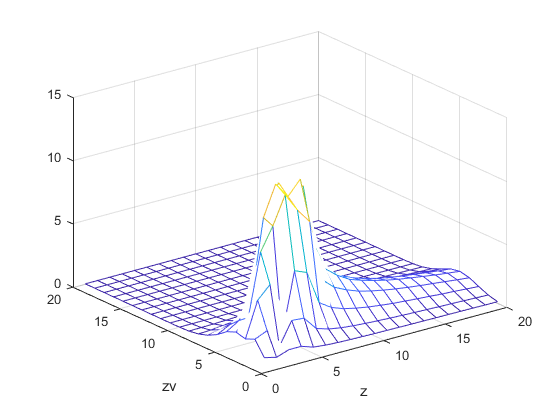

figure
mesh(Int_sum1)
xlabel('z')
ylabel('zv')

eig_values = eig(Int_sum1);
moduleeig = abs(eig_values);

ligth_start_coordX = -126.3:12.730/2:0; %координаты источника света
ligth_start_coordX = ligth_start_coordX(1:19);
SKO = sqrt(150);
matoh = -100;
a = 1/(SKO*sqrt(2*pi));
c = SKO;
b = matoh;
f = a * exp(-(ligth_start_coordX - b).^2/(2*c.^2));
% f(1:5) = 0;
% f(6:8) = 10;
% f(9:10) =0;

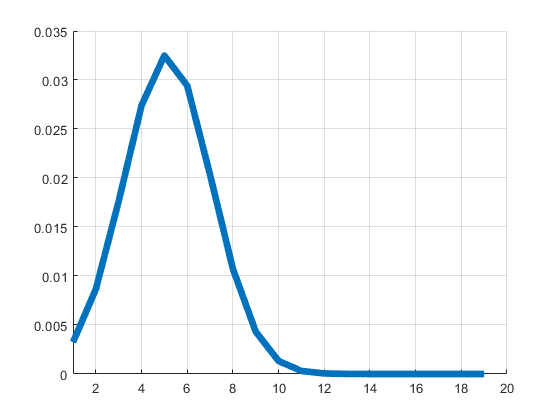

close
load('Result_comp_20_20_intsum.mat')
resultsum_111 = sum(Int_sum,1);
resultsum_111 = resultsum_111(end:-1:1);
% fprintf('SKO = %d;\n',((sum(f-b).^2)));
% fprintf('MSKO = %d;\n',((sum(f-b).^2))/(sum(b)/length(b)));

figure

hold on 
% plot(b, 'LineWidth',4)
plot(f, 'LineWidth',5)
% plot(smooth(b,1), 'LineWidth',0.1)
grid on
xlim([value_start value_end])

figure
error = 0.1* max(resultsum_111)

error = 4.6973

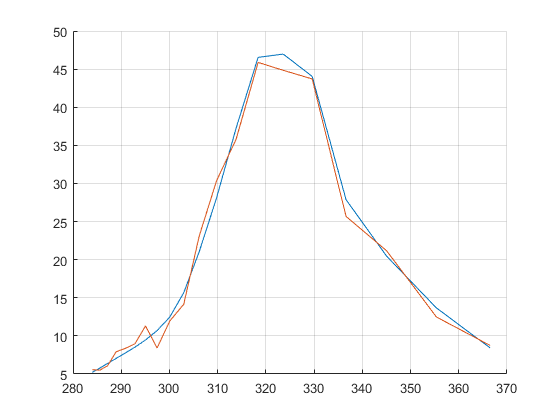

resultsum_11 = resultsum_111 - error/2 + error*(rand(length(resultsum_111),1))';
resultsum_11 = smooth(resultsum_11,1)';
load('y1');
y_cord = 0:126/19:126;
fiber_cord = zeros(size(y_cord));
for i = 1:length(y_cord)
    [~, fiber_cord(i)] = min(abs(y2 - y_cord(i)));
end
Result_for_matlab = fiber_cord/length(y2).*(366.5-284)+284;
hold on 
plot(Result_for_matlab,resultsum_111, 'LineWidth',0.5)
plot(Result_for_matlab,resultsum_11, 'LineWidth',0.5)
% plot(smooth(b,1), 'LineWidth',0.1)
grid on

Регуляризация по Тихонову

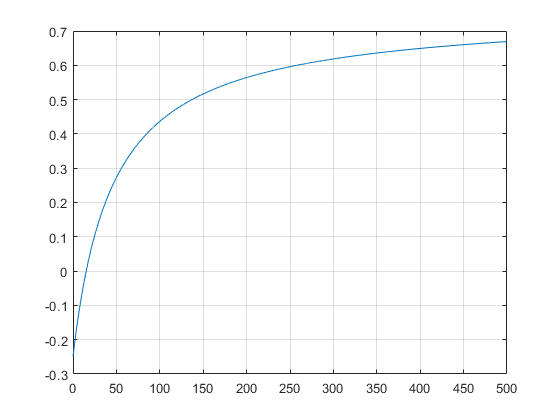

alpha = 0:0.01:500;
T = zeros(1,length(alpha));
R = zeros(length(alpha),value_end-value_start+1);
for i = 1:length(alpha)
    F = Int_sum1.' * Int_sum1  + alpha(i) .* eye(size(Int_sum1));
    R(i,:) = resultsum_11*(inv(F)*Int_sum1.');
    T(i) = sqrt(sum(((R(i,:)*Int_sum1)-resultsum_11).^2)) - 0.25;
end
figure
plot(alpha,T)
% ylim([-0.01 0.01])
% xlim([0 5])
grid on

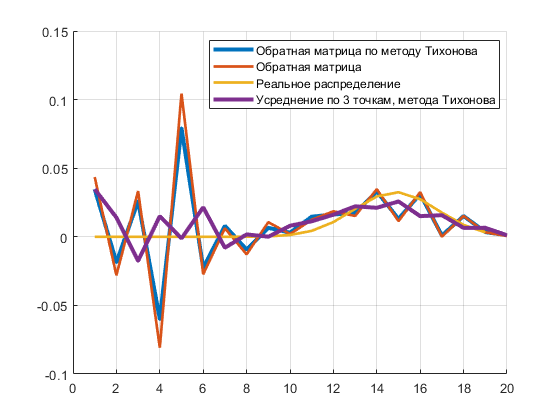

[~,I_r] = min(abs(T));
figure
b = resultsum_11/Int_sum1;
hold on
grid on
plot(R(I_r,:),'LineWidth',3)
plot(b, 'LineWidth',2)
plot(f(end:-1:1), 'LineWidth',2)
plot(smooth(R(I_r,:),3),'LineWidth',3)
legend('Обратная матрица по методу Тихонова', 'Обратная матрица','Реальное распределение','Усреднение по 3 точкам, метода Тихонова', 'Location', 'best')

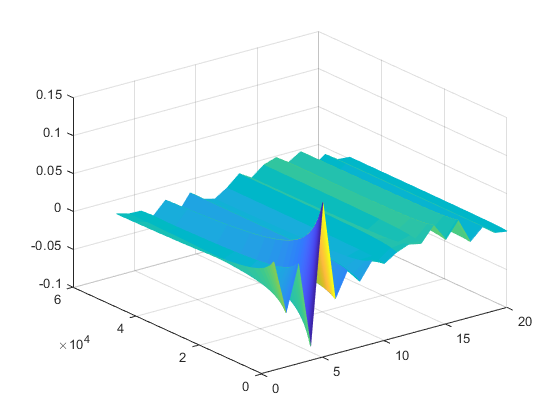

figure
mesh(R)

% zlim([-800 1000])


clc
load('Result_comp.mat')

value_start = 1;
value_end = 20;
ligth_start_coordX = 0:0.1:10;
Int_result = zeros(size(result,1),value_end-value_start+1,value_end-value_start+1);
for i = 1:size(result,1)
    Int_result(i,:,:) = 2*pi*0.1*ligth_start_coordX(i)*result(i,value_start:value_end,value_start:value_end);
end
Int_result_sum = sum(Int_result,1);
Int_sum(:,:) = Int_result_sum(1,:,:);
Int_sum1 = Int_sum(:,:);
for i = size(Int_result_sum,2)
    Int_sum1(i,:) = Int_result_sum(1,i,:);
end
pname = 'D:\Turboshaft\разрешение\2019_12_27_MIDL';
oldFolder = cd(pname);
List_file = dir;
Load_file = zeros(length(List_file)-2, 3648);
for i = 3:length(List_file)
    preload = load(string(List_file(i).name));
    Load_file(i-2,:) = preload(3,:);
end
cd(oldFolder)
% C2_pic = Load_file(end:-1:1,1000)';
C2_pic = Load_file(1:end,997)';
% C2_pic = C2_pic/max(C2_pic);


step_alpha = 1;
alpha = 0:step_alpha:2000;
T = zeros(1,length(alpha));
R = zeros(length(alpha),value_end-value_start+1);
for i = 1:length(alpha)
    F = Int_sum1.' * Int_sum1  + alpha(i) .* eye(size(Int_sum1));
    R(i,:) = smooth(C2_pic,1)'*(inv(F)*Int_sum1.');
    T(i) = sqrt(sum(((R(i,:)*Int_sum1)-smooth(C2_pic,1)').^2));
end
b = C2_pic*inv(Int_sum1);
figure
hold on
plot(diff(diff(abs(T(1:end)))*600))
plot(abs(T(1:end)))
% ylim([-0.01 0.01])
grid on

[~,I_r] = min(diff(abs(T(1:end))))

I_r = 559

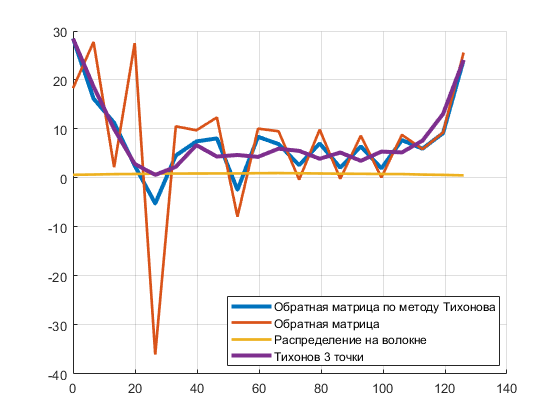


% figure
% hold on
% grid on
% plot(R(I_r,:),'LineWidth',3)
% plot(C2_pic,'LineWidth',3)
% 
% xlim([0.0 20.0])
x_axes = 0:126/19:126;
figure
hold on
grid on
plot(x_axes,R(I_r,:),'LineWidth',3)
plot(x_axes,b, 'LineWidth',2)
plot(x_axes,C2_pic/max(C2_pic), 'LineWidth',2)
plot(x_axes,smooth(R(I_r,:),3),'LineWidth',3)
legend('Обратная матрица по методу Тихонова', 'Обратная матрица','Распределение на волокне','Тихонов 3 точки', 'Location', 'best')

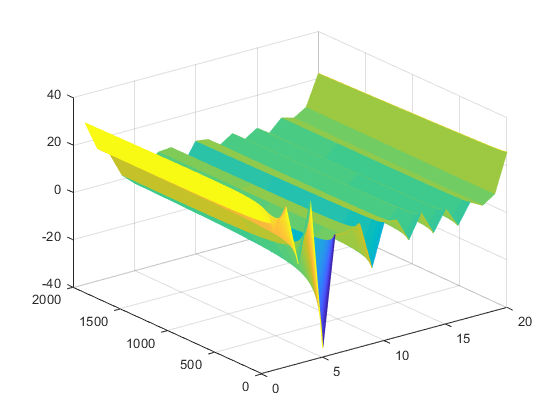


% ylim([-32 743])
% plot(C2_pic/Int_sum1,'LineWidth',3)
figure
mesh(R)

% zlim([-8000 15000])